# Hierarchical clustering

Clear workspace

clear all; clc; close all;

## Example 1

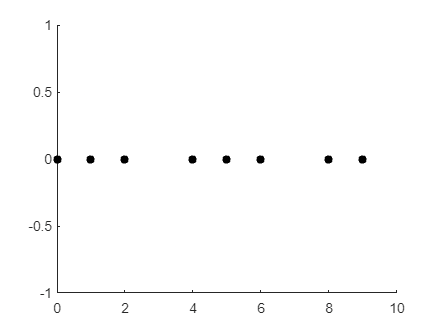

X=[0 1 2 4 5 6 8 9]';
y=zeros(size(X,1),1);
figure(1)
clf
hold on
scatter(X,y,'ko',filled='s')
hold off

Linkage

Z=linkage(X)

Z =      7     8     1
     1     2     1
     3    10     1
     5     6     1
     4    12     1
     9    13     2
    11    14     2


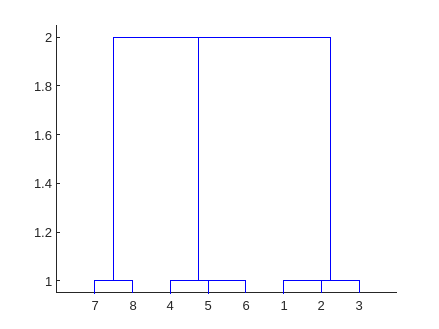

figure(2)
dendrogram(Z)

## Example 2

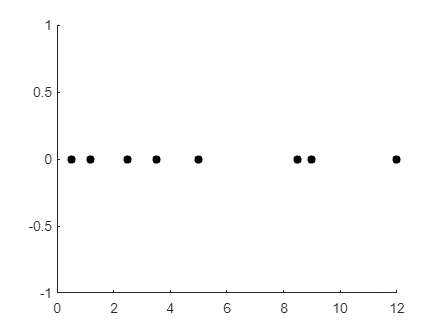

X=[0.5 1.2 2.5 3.5 5 8.5 9 12]';
y=zeros(size(X,1),1);
figure(3)
clf
hold on
scatter(X,y,'ko',filled='s')
hold off

Linkage

Z=linkage(X)

Z =     6.0000    7.0000    0.5000
    1.0000    2.0000    0.7000
    3.0000    4.0000    1.0000
   10.0000   11.0000    1.3000
    5.0000   12.0000    1.5000
    8.0000    9.0000    3.0000
   13.0000   14.0000    3.5000


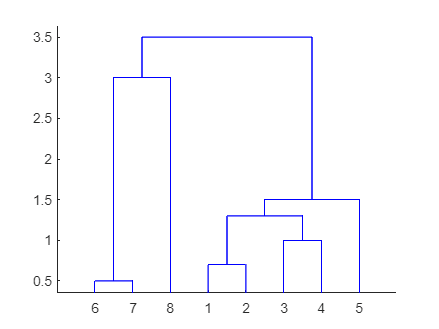

figure(4)
dendrogram(Z)

## Grades dataset

grades = readtable('grades_km_input.csv');
X = table2array(grades(:,2:4));

### Euclid distance

Z=linkage(X)

Z = 1.0e+03 *

    0.4110    0.4520         0
    0.0010    0.0480         0
    0.0350    0.6220         0
    0.0020    0.6230         0
    0.0250    0.6240         0
    0.2090    0.2890         0
    0.2280    0.2750         0
    0.2420    0.2510         0
    0.0080    0.0650         0
    0.0060    0.0540         0


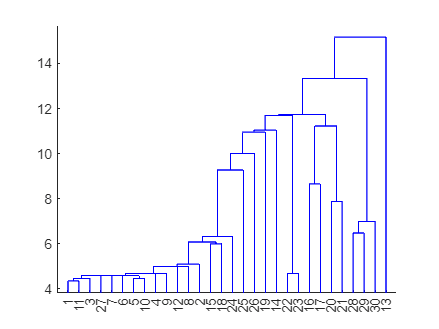

figure(10)
dendrogram(Z)

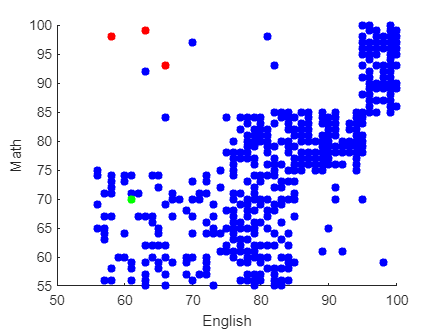

T = cluster(Z,'maxclust',3);

g1 = T==1;
g2 = T==2;
g3 = T==3;

figure(11)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,2),'ro',filled='s')
scatter(X(g2,1),X(g2,2),'bo',filled='s')
scatter(X(g3,1),X(g3,2),'go',filled='s')
xlabel('English')
ylabel('Math')
hold off

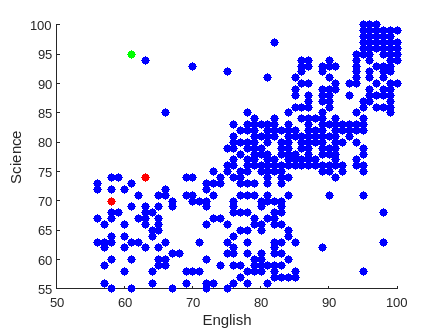


figure(12)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,3),'ro',filled='s')
scatter(X(g2,1),X(g2,3),'bo',filled='s')
scatter(X(g3,1),X(g3,3),'go',filled='s')
xlabel('English')
ylabel('Science')
hold off

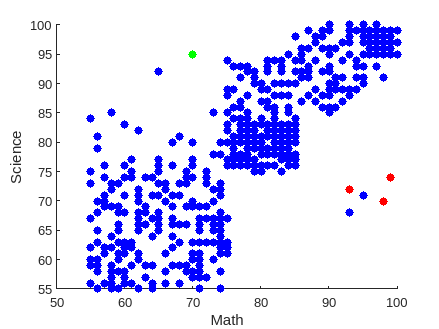


figure(13)
clf
hold on
% Represent cluster elements
scatter(X(g1,2),X(g1,3),'ro',filled='s')
scatter(X(g2,2),X(g2,3),'bo',filled='s')
scatter(X(g3,2),X(g3,3),'go',filled='s')
xlabel('Math')
ylabel('Science')
hold off

### Euclid distance with Ward algorithm

Z=linkage(X,'ward')

Z = 1.0e+03 *

    0.0350    0.0480         0
    0.0010    0.6210         0
    0.0030    0.0470         0
    0.0130    0.0290         0
    0.0050    0.0120         0
    0.0060    0.0540         0
    0.0020    0.6220         0
    0.0080    0.0650         0
    0.0090    0.0590         0
    0.0360    0.0370         0


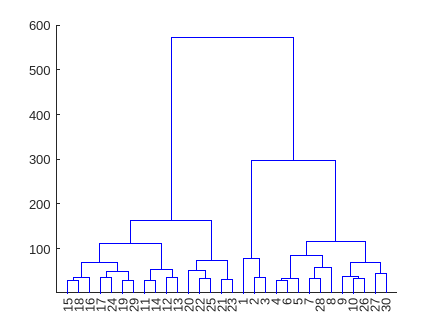

figure(20)
dendrogram(Z)

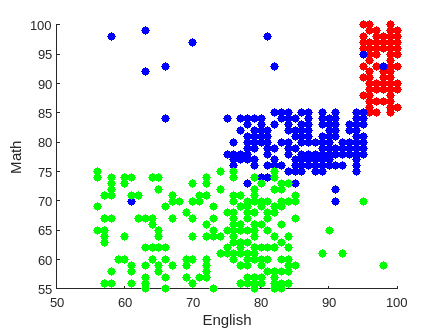

T = cluster(Z,'maxclust',3);

g1 = T==1;
g2 = T==2;
g3 = T==3;

figure(21)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,2),'ro',filled='s')
scatter(X(g2,1),X(g2,2),'bo',filled='s')
scatter(X(g3,1),X(g3,2),'go',filled='s')
xlabel('English')
ylabel('Math')
hold off

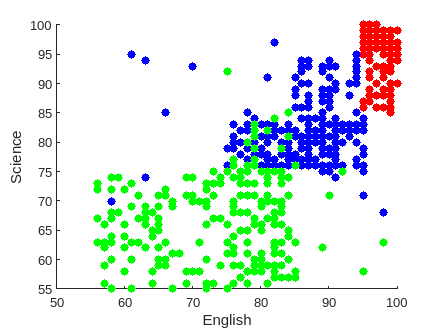


figure(22)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,3),'ro',filled='s')
scatter(X(g2,1),X(g2,3),'bo',filled='s')
scatter(X(g3,1),X(g3,3),'go',filled='s')
xlabel('English')
ylabel('Science')
hold off

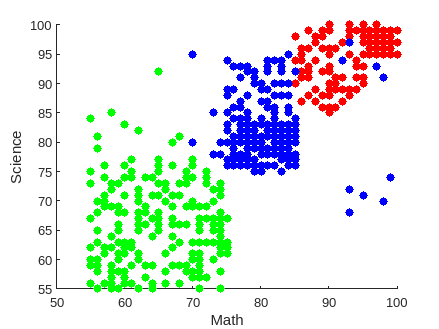


figure(23)
clf
hold on
% Represent cluster elements
scatter(X(g1,2),X(g1,3),'ro',filled='s')
scatter(X(g2,2),X(g2,3),'bo',filled='s')
scatter(X(g3,2),X(g3,3),'go',filled='s')
xlabel('Math')
ylabel('Science')
hold off